# **Distributed-parameter transducer model**

# **for the stepped amplitude transformer**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

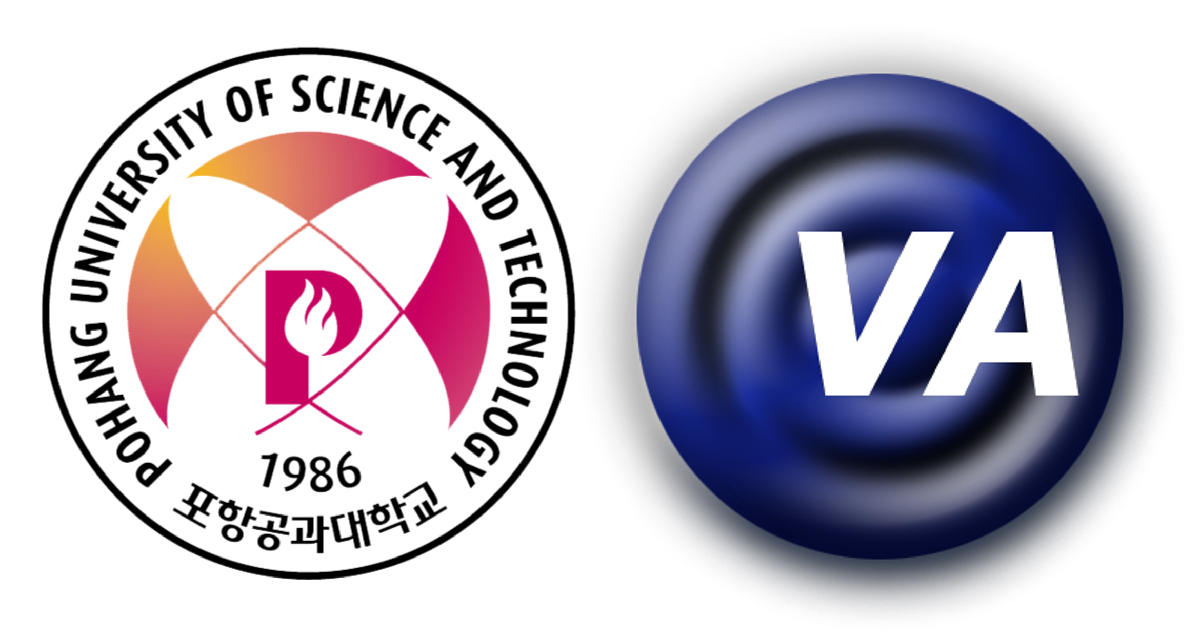

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Define the simulation frequency
% f = 75e3;   % 75 [kHz]
syms f

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');

% Load the plate's impedance
[~,Z_p_wo_steps] = import_impedance('D -230725 - Stepped-plate impedance w.o. steps.txt');
[~,Z_p_w_steps] = import_impedance('D -230725 - Stepped-plate impedance w. steps.txt');

% Define the structure
n_start = 1;    % Start index of node;
n_end   = 5;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    4
The number of nodes:       5


e_piezo = 2;  % Index of piezoelectric bar

% Initialize the symbols for material properties and design parameters of elements

% Mechanical
rho = sym('rho_%d', [1 n_end]); % Density
E   = sym('E_%d',   [1 n_end]); % Young's modulus
nu  = sym('nu_%d',  [1 n_end]); % Poisson ratio
c   = sym('c_%d',   [1 n_end]); % Longitudinal wave speed
k   = sym('k_%d',   [1 n_end]); % Longitudinal wave number
l   = sym('l_%d',   [1 n_end]); % Length of element
A   = sym('A_%d',   [1 n_end]); % Area of element
Z_p = sym('Z_p');               % Mehcanical impedance of plate

% Electircal
eps_33  = sym('eps_33');        % Dielectric constant, eps_33
N_piezo = sym('N_piezo');       % Number of Piezo

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33


The effort and flow variable vectors are $\mathbf{F}=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $\mathbf{u}=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end]).';
u   = sym('u_%d',[1 n_end]).';
V   = sym('V');


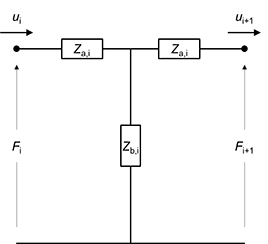

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

By the KCL,


$$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]$$


% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

% rho(1:n_start-1)    = [];
% c(1:n_start-1)      = [];
% k(1:n_start-1)      = [];
% l(1:n_start-1)      = [];
% A(1:n_start-1)      = [];


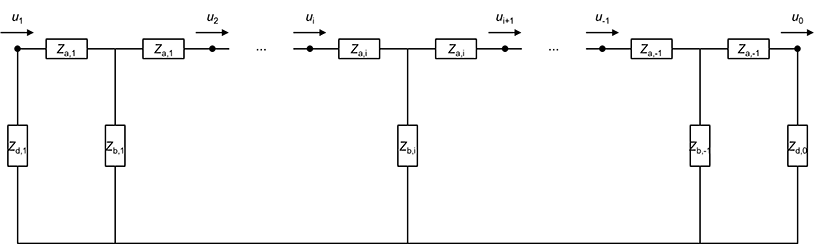

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $\mathbf{F}=\mathbf{Z} \cdot \mathbf{u}=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,-1}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end n_end]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i-1:i));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end-1) + Z_d(n_end);

Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} Z_{d,1}-\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{d,5}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

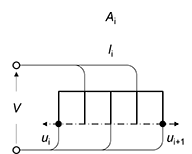

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

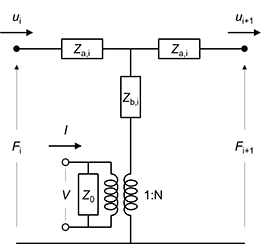

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}+NV\cr
-F_{i+1}-NV\cr
}
\right]$where $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}$

N = N_piezo*A(e_piezo)*d_33*E(e_piezo)/l(e_piezo);

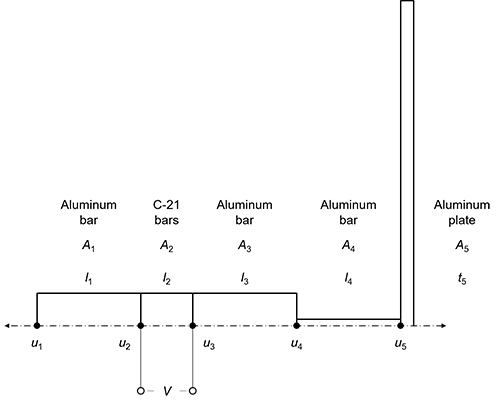

**Figure 5** Typical stepped-plate transducer

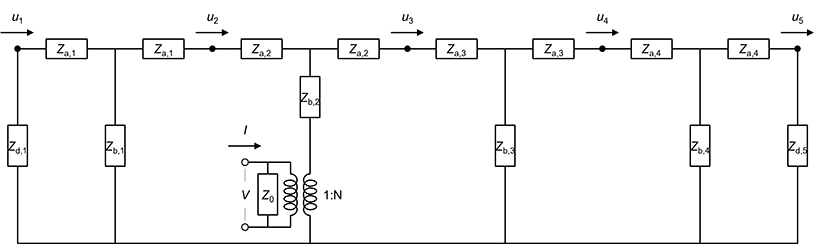

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 \cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} \cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,4}}+Z_{\rm{d,5}} \cr
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
}
\right]

=

\left[
\matrix{
0\cr
NV\cr
-NV\cr
0\cr
0\cr
}
\right]$$


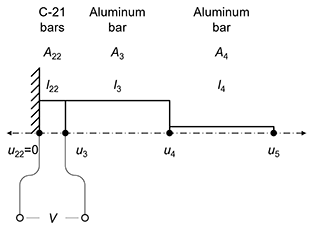

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

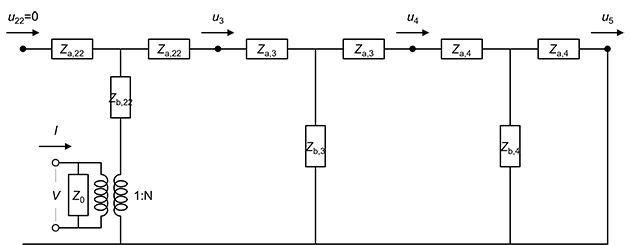

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% For the stepped horn

% Applying the volume conditions as material properties

% Define the bounrady conditions of both ends
Z = subs(Z, [Z_d(n_start) Z_d(n_end)], [0 Z_p]);
Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} -\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{p}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

Define the boundary conditions

- Velocity at node 22, $u_{22}=0$

% u = subs(u, u(n_start), 0);
u(1:n_start-1)  = [];
u

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4}\\ u_{5} \end{array}\right)$$

Define the force conditions

- Force at node 22, $F_{22}=NV$

- Force at node 3, $F_{3}=-NV$

F = subs(F, F(1:e_piezo-1), zeros(e_piezo-1,1));
F = subs(F, F(e_piezo), N*V);
F = subs(F, F(e_piezo+1), - N*V);
F = subs(F, F(e_piezo+2:end), zeros(n_end - e_piezo - 1,1));
F(1:n_start-1)  = [];
F

$$F = \left(\begin{array}{c} 0\\ \frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ -\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ 0\\ 0 \end{array}\right)$$

Solve $\mathbf{Z}\cdot \mathbf{u}=\mathbf{F}$

eqn = Z*u == F

$$eqn = \begin{array}{l} \left(\begin{array}{c} -A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{2}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}=0\\ -u_{2}\,\left(A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\sigma_{3}\right)+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}=\sigma_{4}\\ -u_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{4}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}=-\sigma_{4}\\ -u_{4}\,\left(\sigma_{2}+\sigma_{1}\right)+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0\\ u_{5}\,\left(Z_{p}-\sigma_{1}\right)+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{2}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{3}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{4}=\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}} \end{array}$$

% for i=2:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i-1),u(i));
% end
% for i=1:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i),u(i));
% end
% u = Z(2:4,2:4)\F(2:4)
u = Z\F

u1 = u(1);
u2 = u(2);
u3 = u(3);

R31 = u3/u1

% Compute simplified symbolic expression
simplifiedExpr = simplify(R31)


% [n,d] = numden(u3);
% eqn = Z*u == F
% u(2) = solve(eqn(1),u(2))
% eqn1 = Z*u == F
% u(3) = solve(eqn1(2),u(3))
% eqn2 = Z*u == F
% u(4) = solve(eqn2(3),u(4))

u = subs(u, A(3), A(2));
u = subs(u, c(4), c(3));
u = subs(u, k(4), k(3));
u = subs(u, rho(4), rho(3))

Substituting the numerical geometric dimensions and material properties into the symbols,

u = subs(u, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
% u = subs(u, [A(2) A(4)],        [pi*7e-3^2  pi*1.5e-3^2]);
u = subs(u, [l(1) l(2) l(3) l(4)],  [12e-3  4e-3    13.9e-3 15.29e-3]);

u = subs(u, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
u = subs(u, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
u = subs(u, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
u = subs(u, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
u = subs(u, d_33,               mat.d33('C-21'));
u = subs(u, N_piezo,            4);

u = subs(u, V, 10);
u

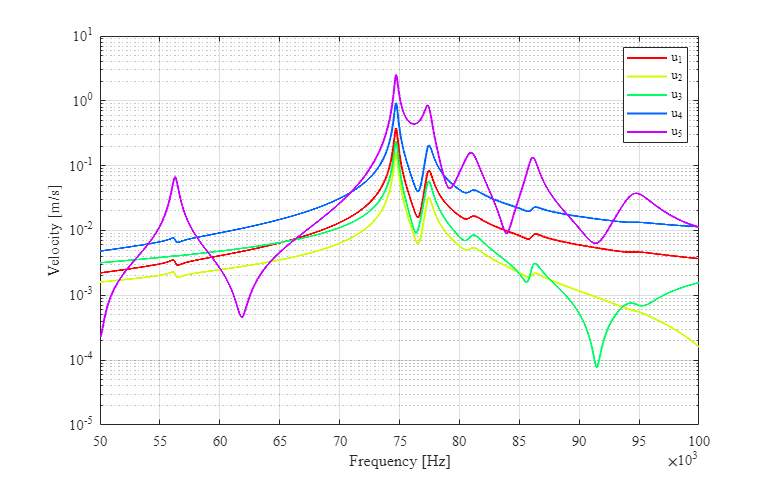

tic
fr_u = symfun(u,f);
fr_u_num = matlabFunction(fr_u);
freq = 50e3:10:100e3;
% u_num = fr_u_num(freq);
u_num_w = fr_u_num(freq,interp1(freq, Z_p_w_steps,freq));
% semilogy(freq, abs(u_num))
% fplot(abs(fr_u(f)),[50e3 100e3])
createfigure_fr(freq, abs(u_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")

toc

Elapsed time is 0.848894 seconds.


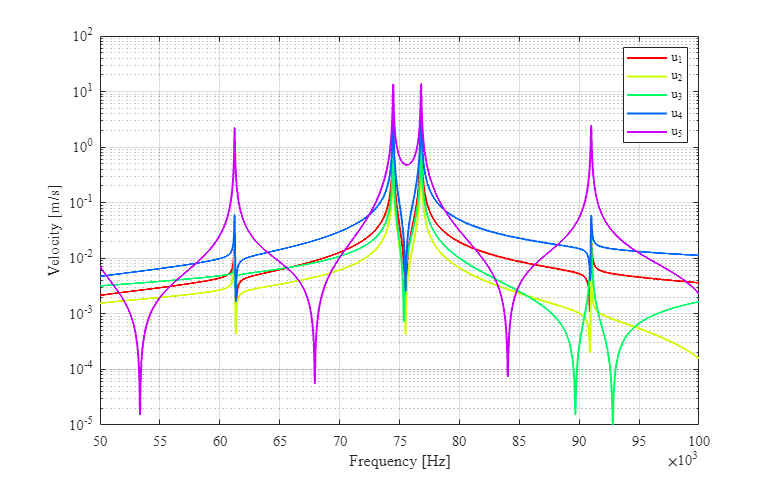

tic
u_num_wo = fr_u_num(freq,interp1(freq, Z_p_wo_steps,freq));
createfigure_fr(freq, abs(u_num_wo)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")

toc

Elapsed time is 0.124888 seconds.


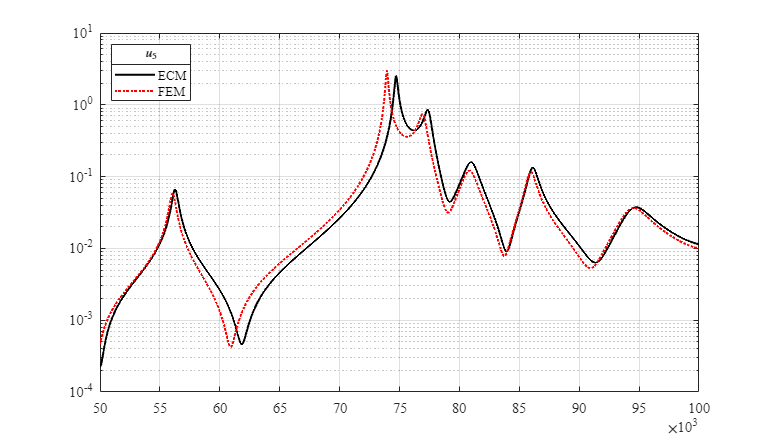

u_OBS_wo    = import_COMSOL('D -230725 - OBS rework by WJ w.o. Steps.txt');
u_OBS_w     = import_COMSOL('D -230725 - OBS rework by WJ w. Steps.txt');

createfigure_fr_comp3(freq, abs(u_num_w(5,:))', u_OBS_w.freq, u_OBS_w.v5, ...
    'northwest',"$u_5$","ECM","FEM",'','','linear','log')

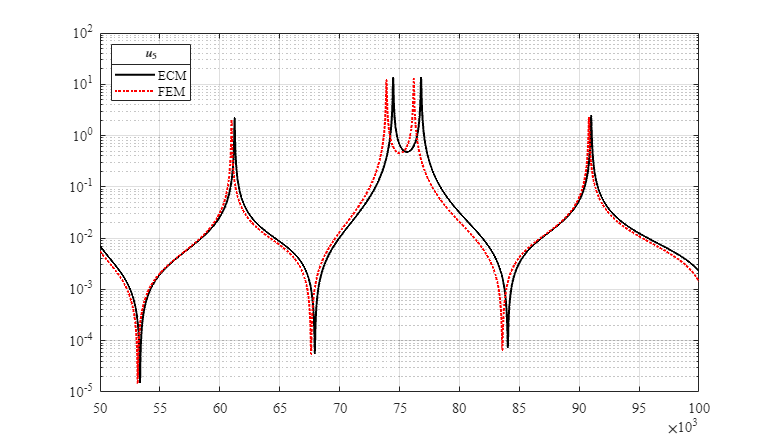

createfigure_fr_comp3(freq, abs(u_num_wo(5,:))', u_OBS_wo.freq, u_OBS_wo.v5, ...
    'northwest',"$u_5$","ECM","FEM",'','','linear','log')


% createfigure_fr_comp(freq, abs(u_num_w(5,:))', u_OBS_w.freq, u_OBS_w.v5, '', "u_5", ...
%     'Frequency [Hz]','Velocity [m/s]','linear','log')
% 
% createfigure_fr_comp(freq, abs(u_num_wo(5,:))', u_OBS_wo.freq, u_OBS_wo.v5, '', "u_5", ...
%     'Frequency [Hz]','Velocity [m/s]','linear','log')